IdMPL = 7;
Id2TA = 1;

load(myProject.FeaturesLists{IdMPL}.Original.Name);

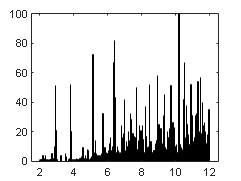

PeakList = myMrgPeakList.PeakList;
ThrArea = prctile(PeakList.chrom_area, 75);
step = 0.02;
axisX = min(PeakList.chrom_Time_IA)-3*step:step:max(PeakList.chrom_Time_IA)+3*step;
histogram(PeakList.chrom_Time_IA, axisX);

Area = myMrgPeakList.TargetedAnalysis{1, 1}.Area;
PeakList = myMrgPeakList.PeakList;
ThNoise = prctile(Area.Values(Area.Values > 0), 5, 'all');
% NoiseLvl =  mean(Area.Values(Area.Values > 0 & Area.Values < ThNoise)) + ...
%     2*std(Area.Values(Area.Values > 0 & Area.Values < ThNoise))
NoiseLvl =  mean(Area.Values(Area.Values > 0 & Area.Values < ThNoise));
ThreNum1 = [10, 106, 10];

IdSel1 =  Area.ID(sum(Area.Values >= 10*NoiseLvl, 2) >= 25);
[~, ~, IdSel1] = intersect(IdSel1, PeakList.ID);
firstPeakList = PeakList(IdSel1, :);
secondPeakList = PeakList;
secondPeakList(IdSel1, :) = [];

## Inititiation

for ii = 1:height(IdSel1)
    Cluster{ii}.Members = ii;
    Cluster{ii}.Tm = firstPeakList.chrom_Time_IA(ii);
    Cluster{ii}.CC = 0;
    Cluster{ii}.SVectorA = Area.Values(Area.ID == firstPeakList.ID(ii), :);
    Cluster{ii}.VectorA = Area.Values(Area.ID == firstPeakList.ID(ii), :);
    VectorTm(ii) = mean(firstPeakList.chrom_Time_IA(ii));
    NbrElement(ii) = 1;
end

%% FIRST LOOP
ThMt = 0.02; % min
ThSim = 0.4;

while 1
    MatStep = NaN(numel(Cluster), numel(Cluster));
    for ii = 1:numel(Cluster)
        for jj = 1:numel(Cluster)
            if ii == jj, continue; end
            if abs(VectorTm(ii) - VectorTm(jj)) > ThMt, continue; end
            if pdist([Cluster{ii}.VectorA; Cluster{jj}.VectorA], 'correlation') > ThSim, continue; end

            testD = sqrt((VectorTm(ii) - VectorTm(jj)).^2 + (pdist([Cluster{ii}.VectorA; Cluster{jj}.VectorA], 'correlation')).^2);
            MatStep(ii, jj) = testD;
        end
    end

    if sum(isnan(MatStep), 'all') == numel(MatStep), break; end
    [l, m] = find(MatStep == min(MatStep, [], 'all', 'omitnan'));

    Cluster{l(1)}.Members = [Cluster{l(1)}.Members, Cluster{m(1)}.Members];
    Cluster{l(1)}.Tm = [Cluster{l(1)}.Tm, Cluster{m(1)}.Tm];
    Cluster{l(1)}.SVectorA = [Cluster{l(1)}.SVectorA; Cluster{m(1)}.SVectorA];
    Cluster{l(1)}.VectorA = sum(Cluster{l(1)}.SVectorA, 1);
    VectorTm(l(1)) = mean(Cluster{l(1)}.Tm);
    NbrElement(l(1)) = NbrElement(l(1)) + 1;
    Cluster(m(1)) = [];
    VectorTm(m(1)) = [];
    NbrElement(m(1)) = [];
end


OptiMe = [];
for ii = 1:numel(Cluster)
    if numel(Cluster{ii}.Members) == 1, continue; end

    OptiMe = [OptiMe; [(Cluster{ii}.Tm - mean(Cluster{ii}.Tm))' (pdist2(Cluster{ii}.VectorA, Cluster{ii}.SVectorA, "correlation")')]];
end

SigmaTm = std(OptiMe(:,1))

SigmaTm = 0.0032

NbrElement(2, :) = 0;
for ii = 1:numel(Cluster)
    IdAdd = find(abs(mean(Cluster{ii}.Tm) - secondPeakList.chrom_Time_IA)/SigmaTm < 3);
    if ~isempty(IdAdd)
        Cluster{ii}.AddMembers = IdAdd;
        NbrElement(2, ii) = numel(IdAdd);

    end

end

Summary = []; flvlListCluster = {}; slvlListCluster = {};
for ii = 1:numel(Cluster)
    if NbrElement(1, ii) > 1
        flvlListCluster{end+1} = firstPeakList(Cluster{ii}.Members, :);
        flvlListCluster{end} = sortrows(flvlListCluster{end},"chrom_intensity_apex","descend");
        Summary(end+1, 1:3) = [flvlListCluster{end}.chrom_Time_IA(1),  flvlListCluster{end}.ms_Accu_mass_1(1), height(flvlListCluster{end})];

        if NbrElement(2, ii) > 0
            slvlListCluster{numel(flvlListCluster)} = [firstPeakList(Cluster{ii}.Members, :); secondPeakList(Cluster{ii}.AddMembers, :)];
            slvlListCluster{numel(flvlListCluster)} = sortrows(slvlListCluster{numel(flvlListCluster)},"chrom_intensity_apex","descend");
            Summary(end, 4) =  height(slvlListCluster{numel(flvlListCluster)});

        else
            Summary(end, 4) = nan;
            
        end

    end


end
Summary(:, 5) = 1:height(Summary);